**This notebook covers different image segmentation techniques using MATLAB.**

Prepared by

*Asif Newaz*

*Lecturer, EEE, IUT*

**Import Images**

img1 = imread("crack_01.jpg")

img1 = 227×227×3 uint8 array
img1(:,:,1) =

   140   143   147   149   148   147   147   147   145   145   146   147   147   146   145   145   154   154   153   153   152   151   150   150   154   154   153   153   153   153   152   152   154   154   153   152   152   151   150   150   152   151   150   152   155   155   152   148   151   151   151   151   151   151   151   151   149   150   151   153   153   152   151   150   152   152   152   151   150   149   148   147   152   149   147   148   152   156   156   155   155   155   154   154   153   152   151   151   148   149   151   152   152   151   150   149   149   150   152   153   153   152   150   149   147   147   147   147   146   145   144   144   144   142   138   137   138   143   147   150   148   148   147   148   149   152   155   156   149   149   149   149   149   151   152   152   146   146   146   147   147   147   148   148   148   148   148   148   148   148   148   148   150   149   147   146   146   147   149  

It is an RGB image of size (227, 227, 3)

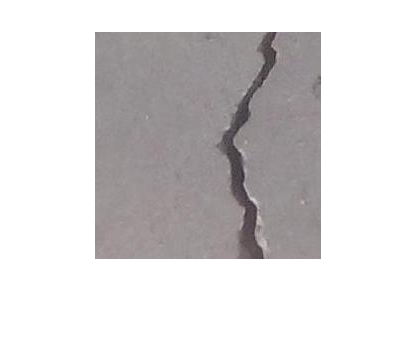

imshow(img1)

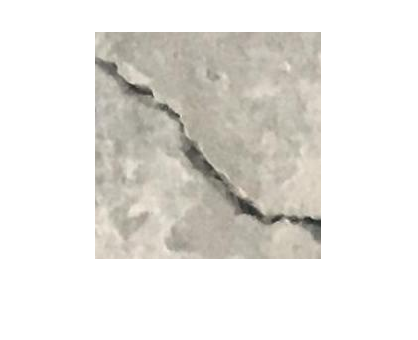

img2 = imread("crack_02.jpg");
imshow(img2)

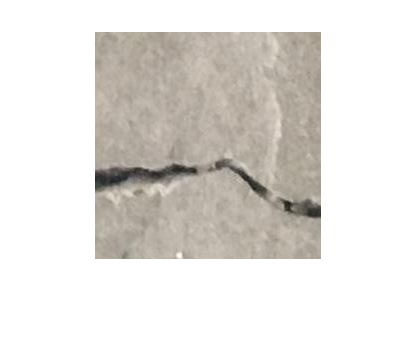

img3 = imread("crack_03.jpg");
imshow(img3)

**Convert to Grayscale**

img1_gray= rgb2gray(img1)

img1_gray = 227×227 uint8 matrix
   137   140   144   146   145   144   144   144   142   142   143   144   144   143   142   142   151   151   150   150   149   148   147   147   151   151   150   150   150   150   149   149   151   151   150   149   149   148   147   147   149   148   147   149   152   152   149   145   148   148
   140   141   142   144   145   145   145   144   143   143   144   145   145   144   143   143   147   147   147   147   147   147   147   147   149   149   149   149   149   149   148   148   151   151   150   149   149   148   147   147   148   147   146   148   150   150   148   145   146   146
   145   142   140   141   145   147   146   144   144   145   146   146   146   146   145   144   143   143   144   144   145   146   147   147   147   147   148   148   148   148   148   148   151   151   150   149   149   148   147   147   147   146   146   147   148   148   147   145   146   146
   149   144   139   140   145   149   147   145   146   146   1

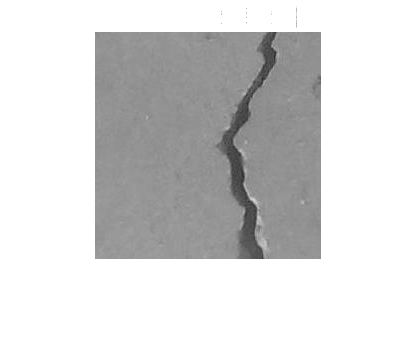

imshow(img1_gray)

img2_gray= rgb2gray(img2);
img3_gray= rgb2gray(img3);

**Global Thresholding**

img1_bin= imbinarize(img1_gray)

img1_bin = 227×227 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   

All the values are converted to binary. The function uses Otsu's method to find the threshold.

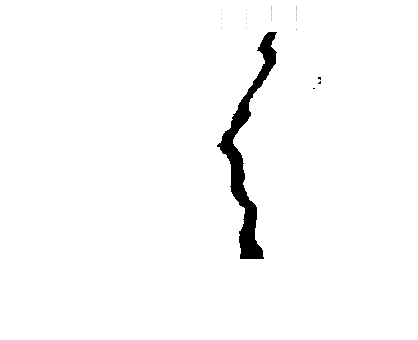

imshow(img1_bin)

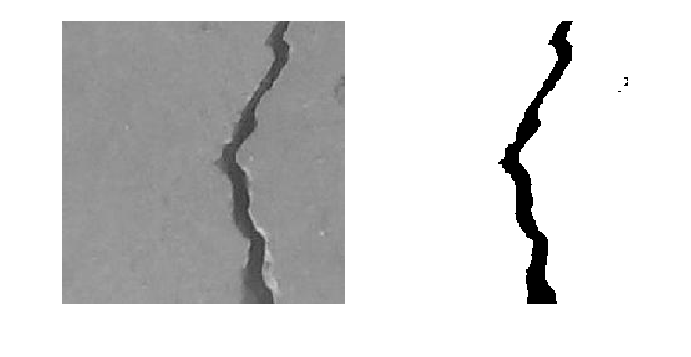

% to compare the two images side-by-side
montage({img1_gray,img1_bin})

img2_bin= imbinarize(img2_gray);
img3_bin= imbinarize(img3_gray);

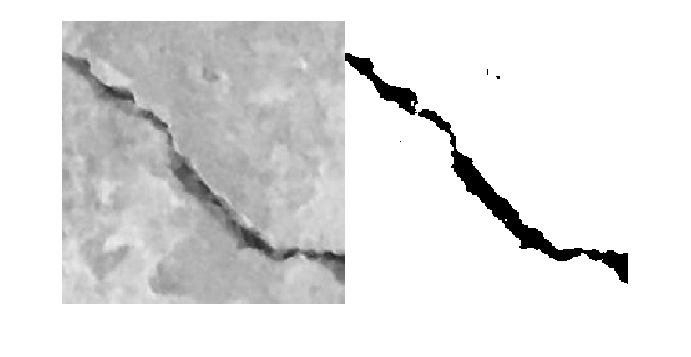

montage({img2_gray,img2_bin})

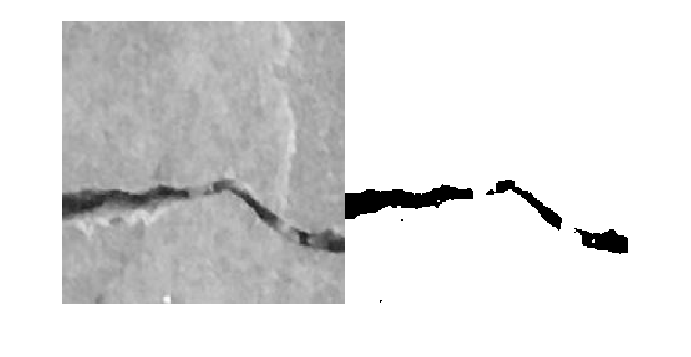

montage({img3_gray,img3_bin})

We can see the binarization is not perfect. There are other techniques (morphology) to get rid of the noisy pixel values.

**Find the threshold**

graythresh(img1_gray)*255

ans = 115

graythresh(img2_gray)*255

ans = 147

graythresh(img3_gray)*255

ans = 128

**Manual Thresholding**

we can also manually change the threshold and see the outcome 

graythresh(img1_gray)

ans = 0.4510

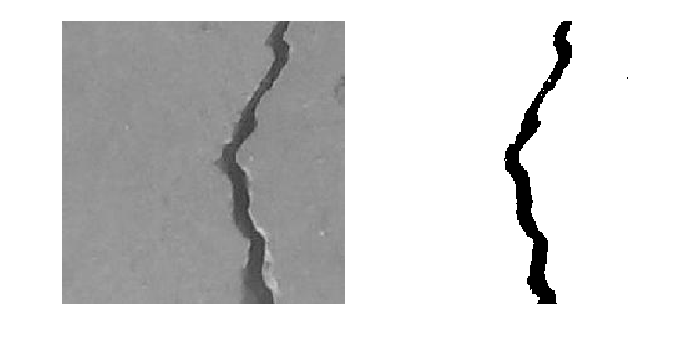

img1_bin_man= imbinarize(img1_gray, 0.4);
montage({img1_gray,img1_bin_man})

**Adaptive Thresholding**

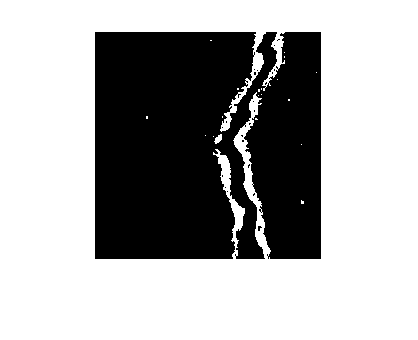

img1_bin_adap= imbinarize(img1_gray,"adaptive");
imshow(img1_bin_adap)

Not needed for this type of images. Required when there is a change in contrast values throughout the image.

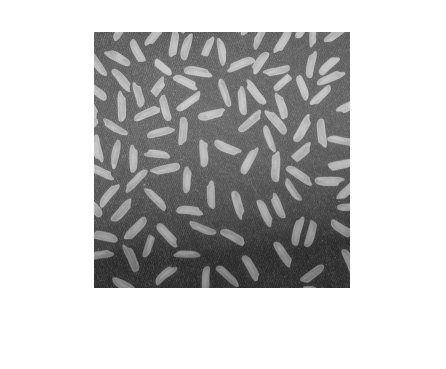

rice = imread('rice.png');
%rice_gray = rgb2gray(rice);
imshow(rice)

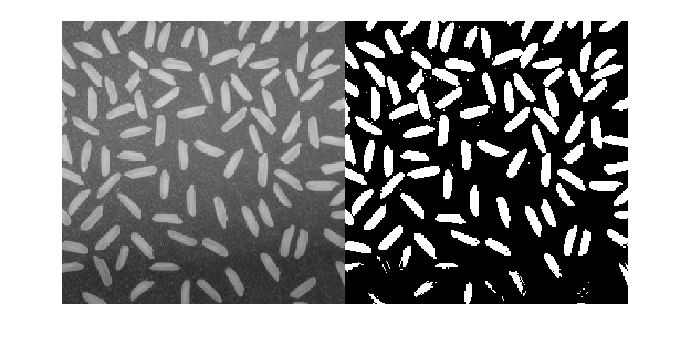

rice_bin= imbinarize(rice,"global");
montage({rice,rice_bin})

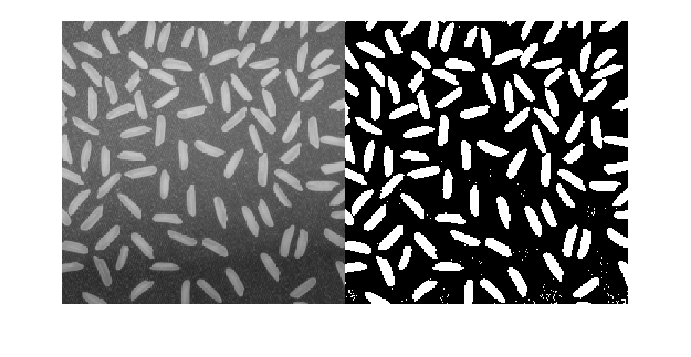

rice_ada= imbinarize(rice,"adaptive");
montage({rice,rice_ada})

**Multilevel Thresholding**

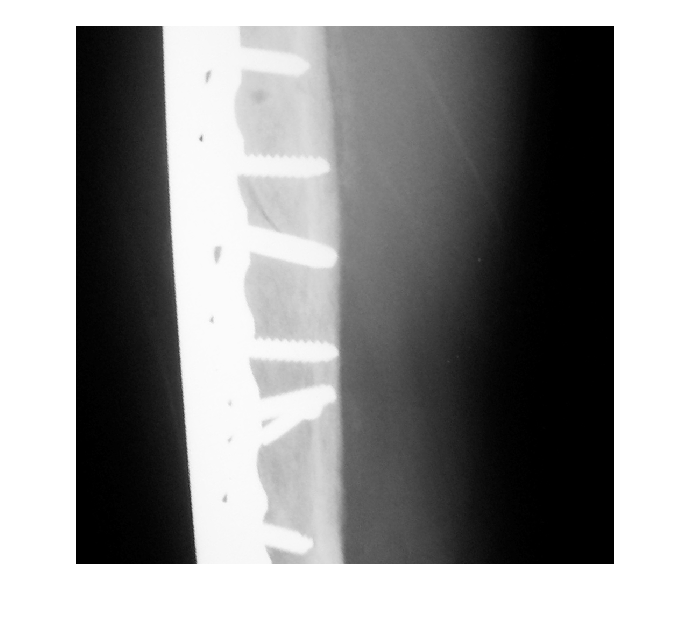

xray = imread('armxray.png');
imshow(xray)

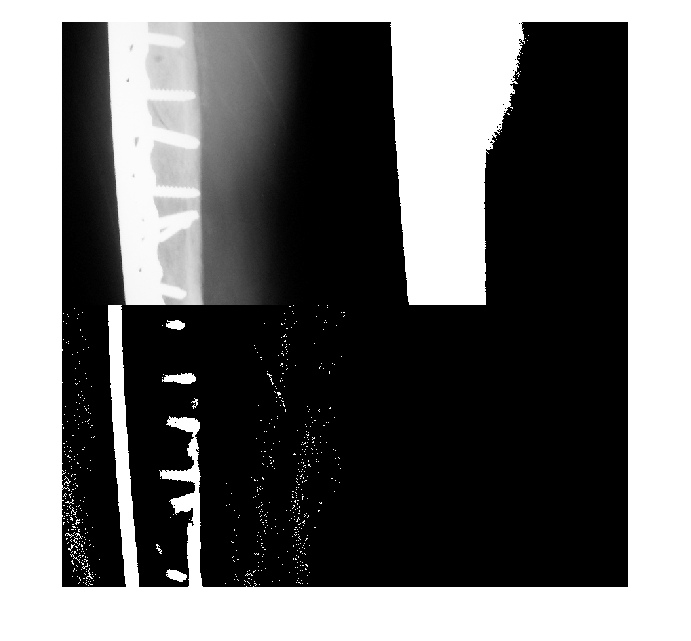

xray_global= imbinarize(xray,"global");
xray_adap = imbinarize(xray,"adaptive");
montage({xray,xray_global, xray_adap})

val= multithresh(xray,3)

val = 1×3 uint8 row vector
    54   147   223


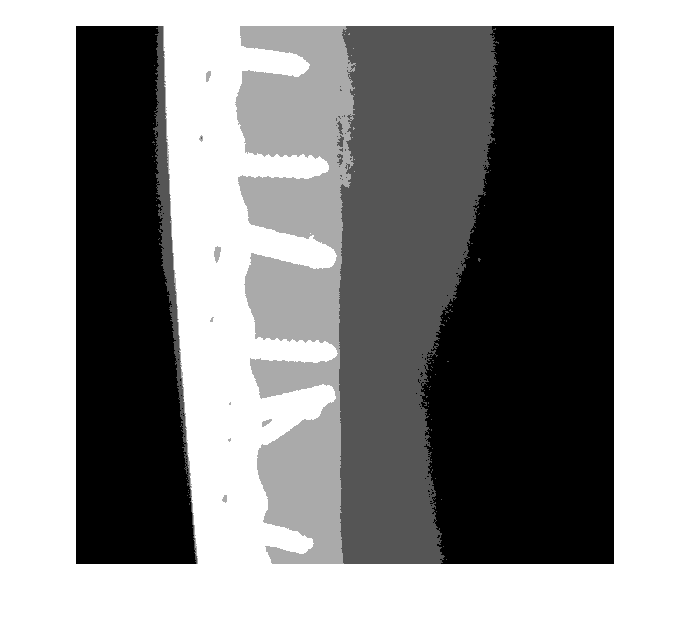

label= imquantize(xray,val);
imshow(label,[])

label_Color = label2rgb(label);

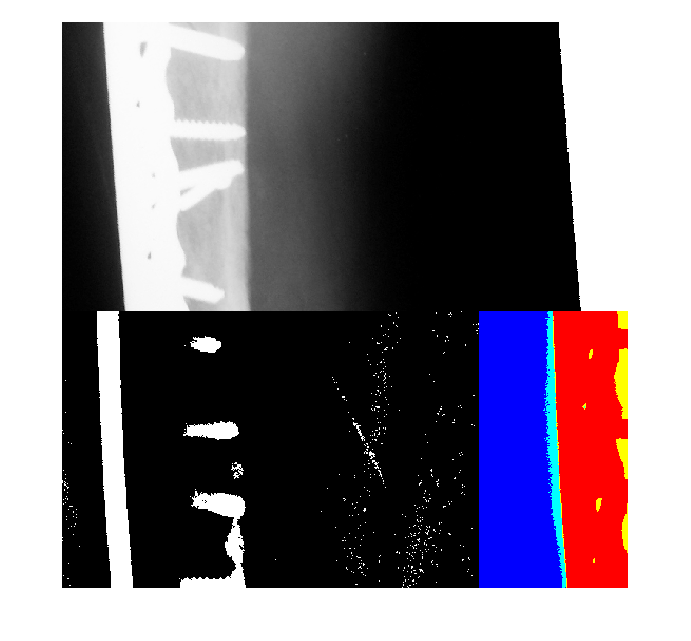

montage({xray,xray_global, xray_adap, label_Color})

**Test on random Image**

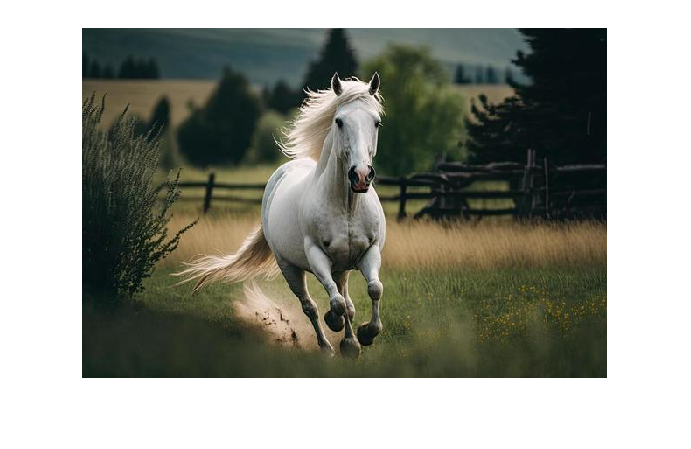

horse= imread("horse.jpg");
imshow(horse)

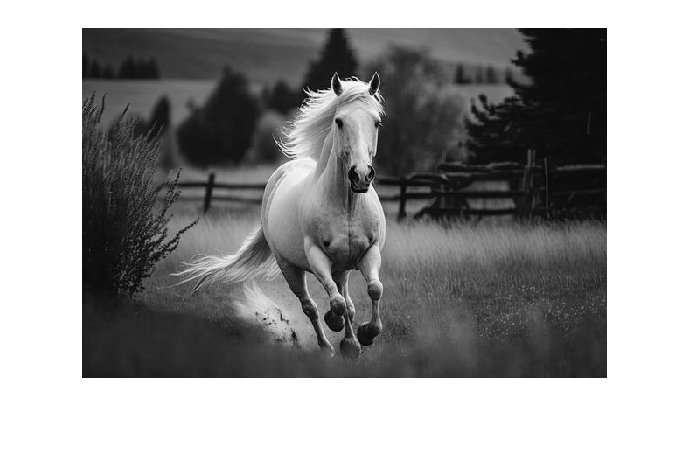

horse_gray= rgb2gray(horse);
imshow(horse_gray)

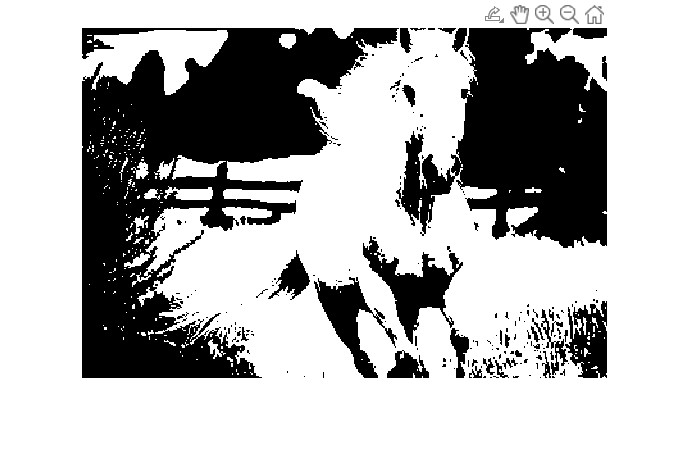

horse_bin = imbinarize(horse_gray);
imshow(horse_bin)

graythresh(horse_gray)

ans = 0.3490

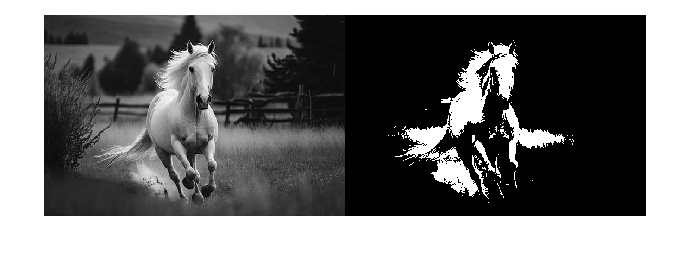

horse_bin_2 = imbinarize(horse_gray,0.55);
montage({horse_gray, horse_bin_2})